# Tic-Tac-Toe Graphical Interface Demo

clear all; close all;

In the template for your graphical Tic-Tac_toe script I included the following lines of code to help you set up your game board interface.

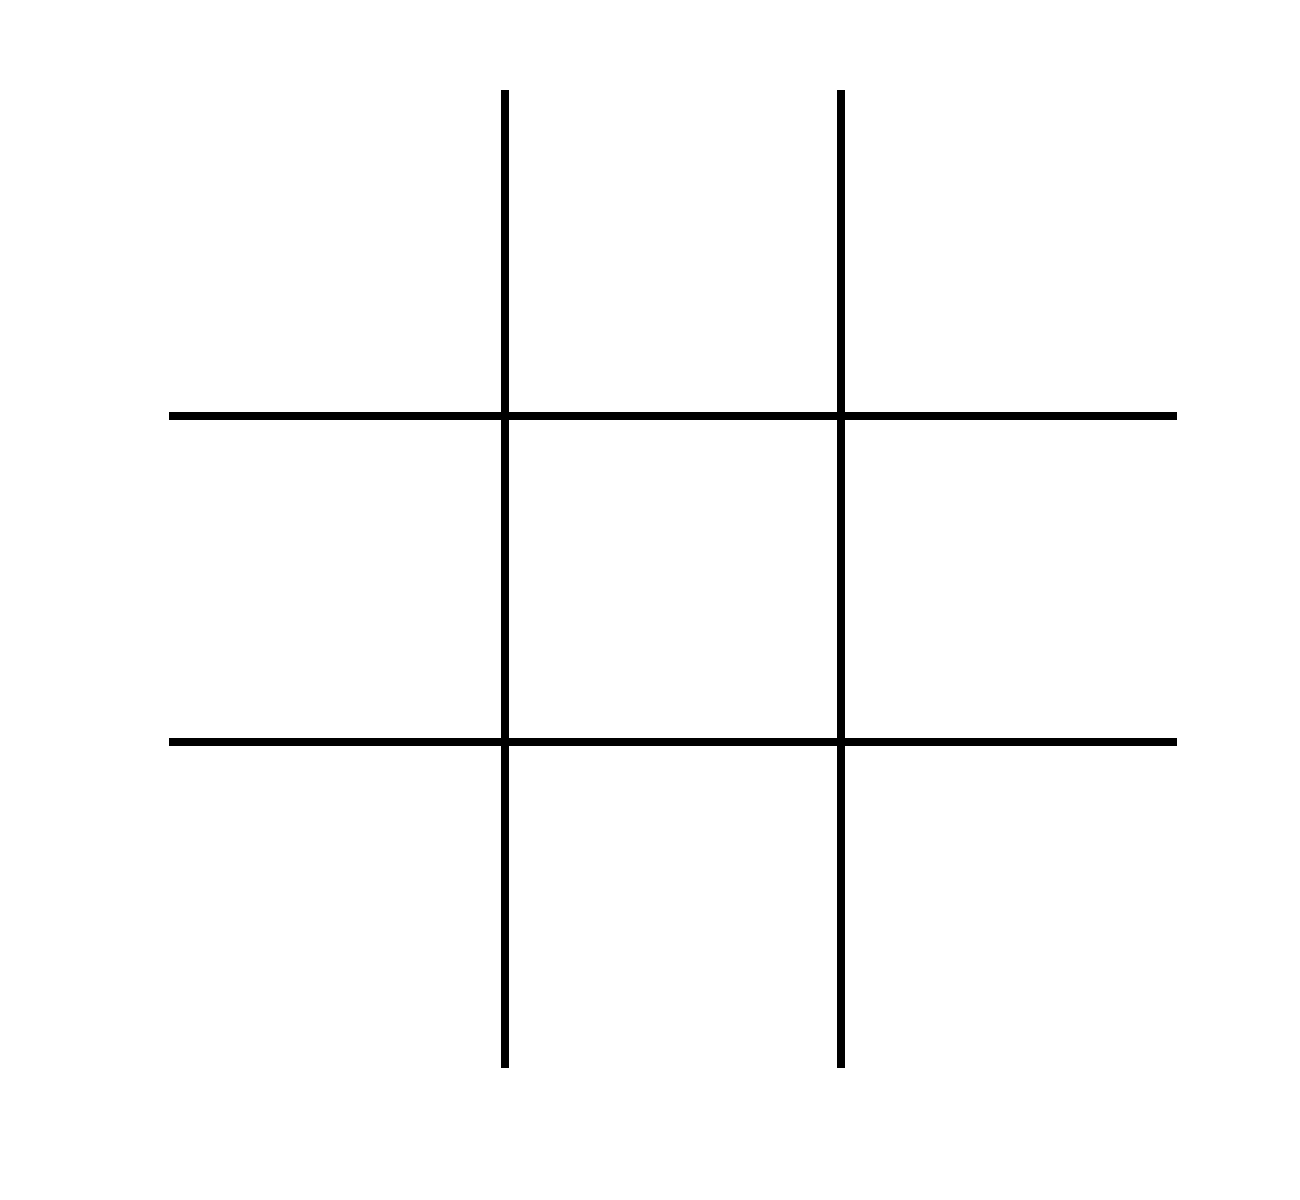

figure('Position',[100,100,650,600]);
axis([0 5 0 5]); 
axis equal;
plot([2 2],[1 4],'k',[3 3],[1 4],'k',[1 4],[2 2],'k',[1 4],[3 3],'k','LineWidth',3)
ax = gca; ax.XColor = 'none'; ax.YColor = 'none'; 

Let's brake down each line so you know how your code works.

- `figure('Position',[100,100,650,600]);`  -  Defines a blank figure with bottom right corner located at the (100,100) point on your computer screen (in pixels) and sets the width to 650 (pixels) and height t0 600 (pixels).  [`See figure` documentation.](https://www.mathworks.com/help/matlab/ref/figure.html?searchHighlight=figure&s_tid=srchtitle_figure_1)

- `axis([0 5 0 5])`  -  Set the $x$ and $y$ axis limits to $0 \le x \le 5$ and $0\le y \le 5$, respectively. [See `axis` documentation.](https://www.mathworks.com/help/matlab/ref/axis.html?searchHighlight=axis&s_tid=srchtitle_axis_1)

- `axis image`  -  Forces the $x$ and $y$ scaling to be equal.

- `plot([2 2],[1 4],'k',[3 3],[1 4],'k',[1 4],[2 2],'k',[1 4],[3 3],'k','LineWidth',3)`  -  plots the black line segments (with width=3) between the specified points. `'k'` is shorthand for black. [See `plot` documentation.](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=srchtitle_plot_1)

- `ax = gca;`  -  Defines `ax` as the current set of axes. [See `gca` documentation.](https://www.mathworks.com/help/matlab/ref/gca.html?searchHighlight=gca&s_tid=srchtitle_gca_1)

- `ax.XColor = 'none'; ax.YColor = 'none';`  -  Sets the color of the current x and y axis to none (invisible). [See axes properties documentation.](https://www.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html)

## `title` command

Part of the game requires you to display feedback to the players. You will do this by adding text to the title, using the `title` command. [See `title` documentation.](https://www.mathworks.com/help/matlab/ref/title.html?s_tid=doc_ta)

Example 1:

Suppose player "O" won the game (determined by the `winner` variable). Display a message in the title indicating that player "O" won.

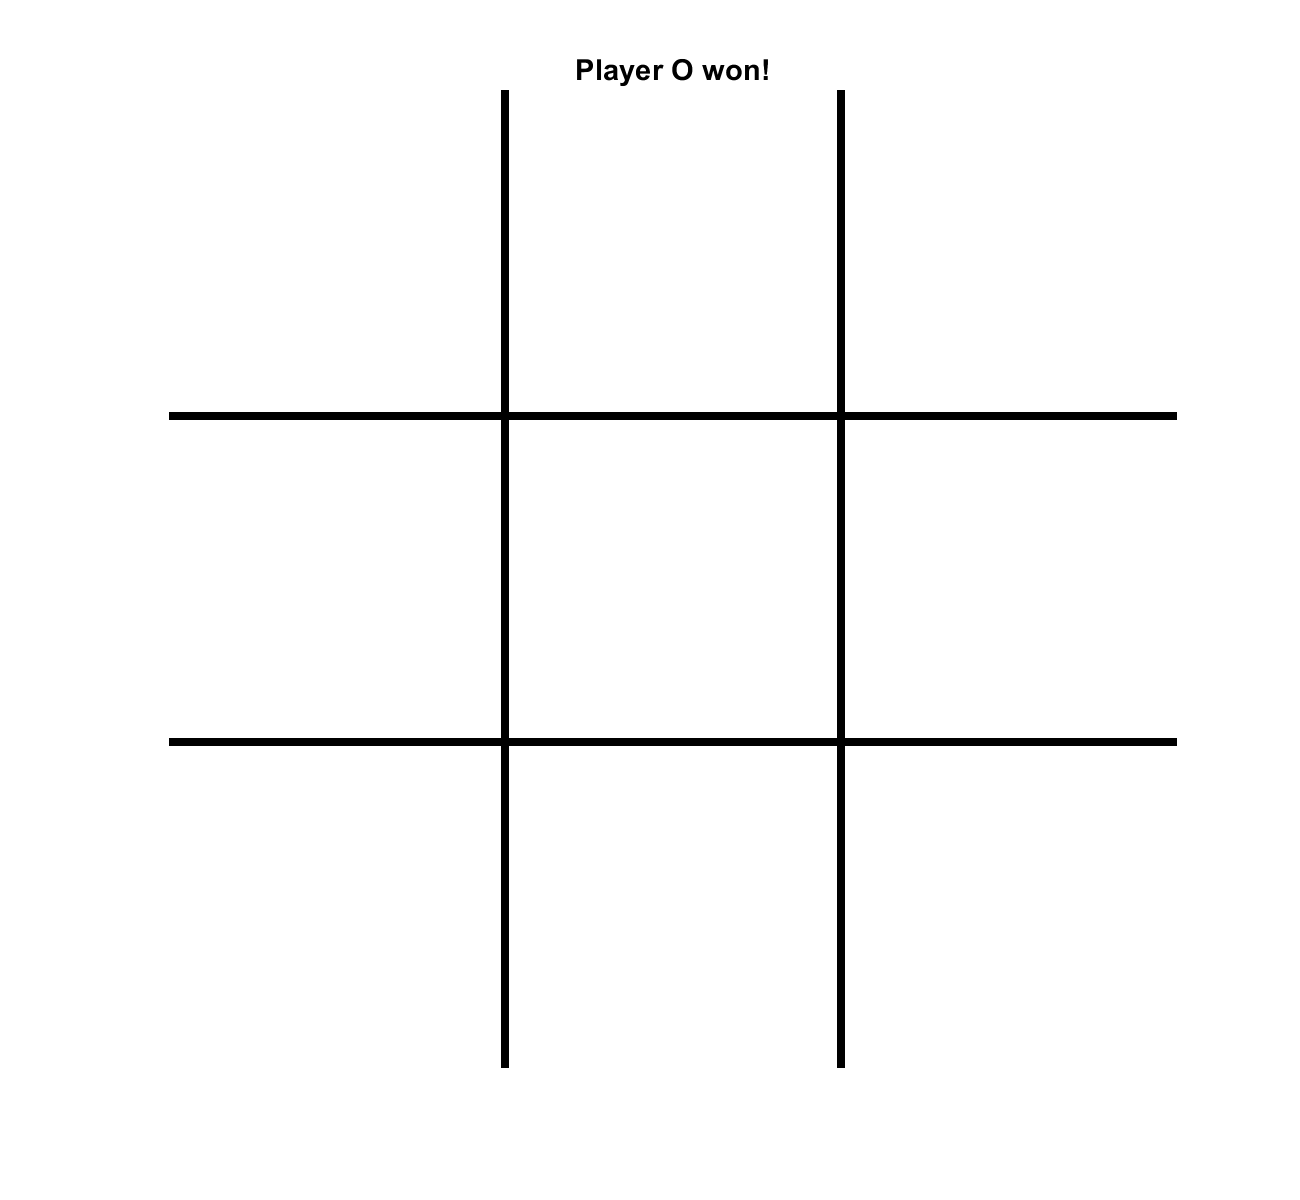

title('Player O won!')

The displayed message is kind of small, so let's increase its size using the 'FontSize' property.

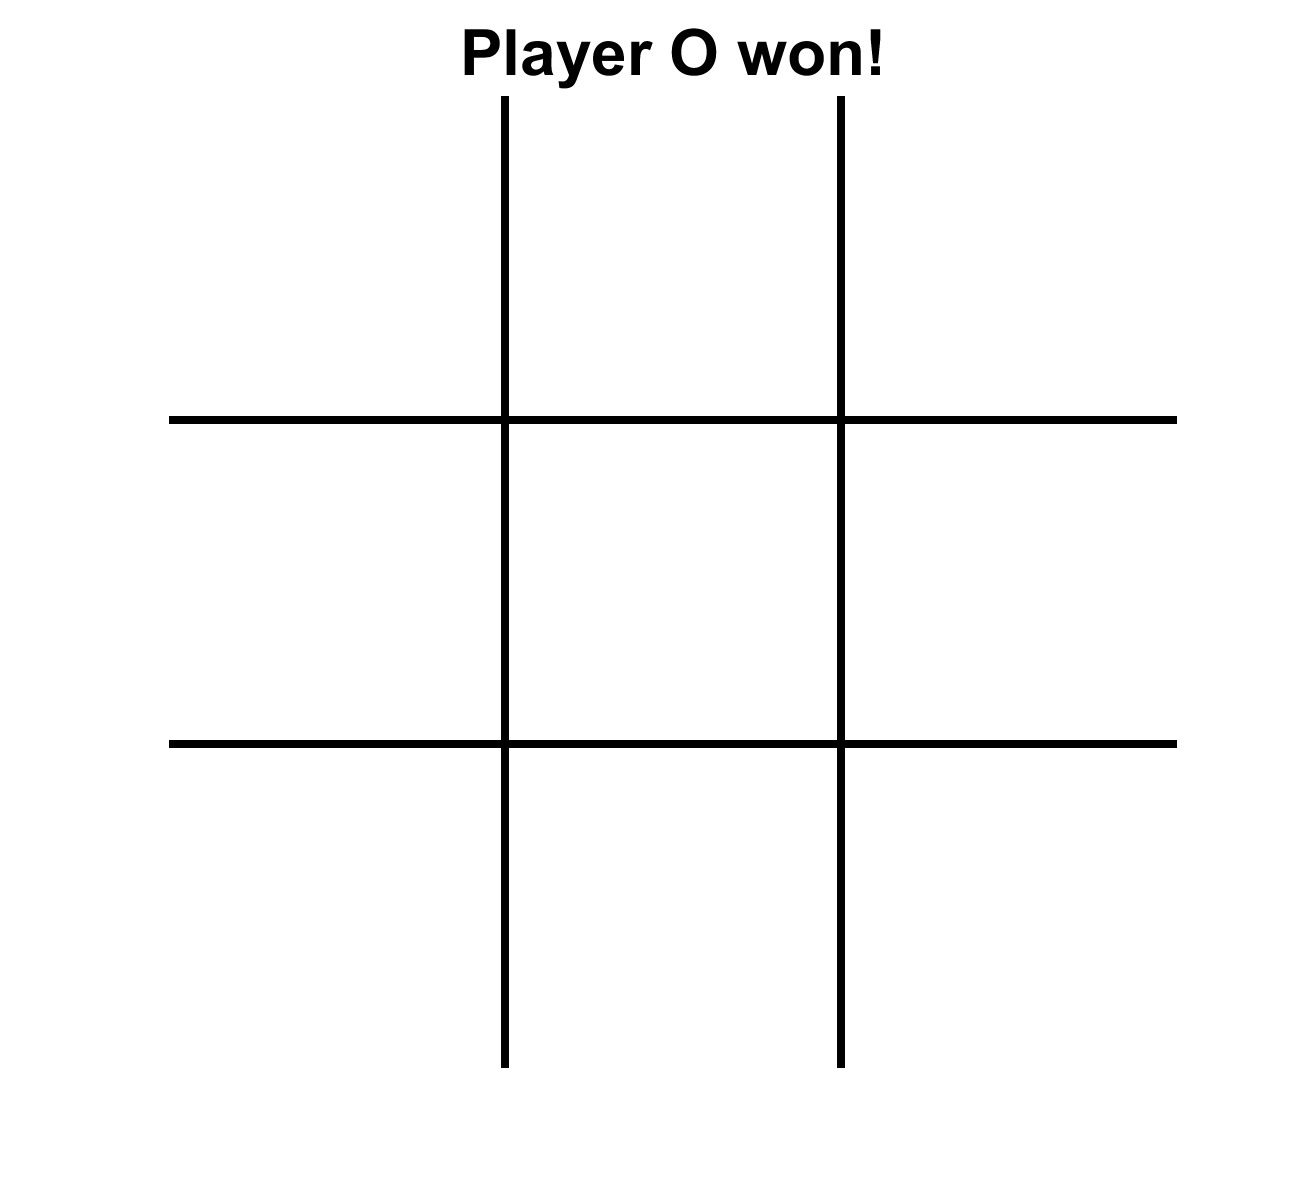

title('Player O won!','FontSize',24)

## `text` command

Another part of the game requires you to place X's and O's on the game board.  We can do this with the `text` command.  [See `text` documentation.](https://www.mathworks.com/help/matlab/ref/text.html?searchHighlight=text&s_tid=srchtitle_text_1)

Here is the basic usage for text on a 2D plot:

`text(x,y,txt)` : places a character array, `txt`, at the point (`x`,`y`)

Example 2:

Place an "X" in the center space.

Note: The bottom left corner of center space is located at (2,2).  Let's try placing an 'X' there and see what we get.

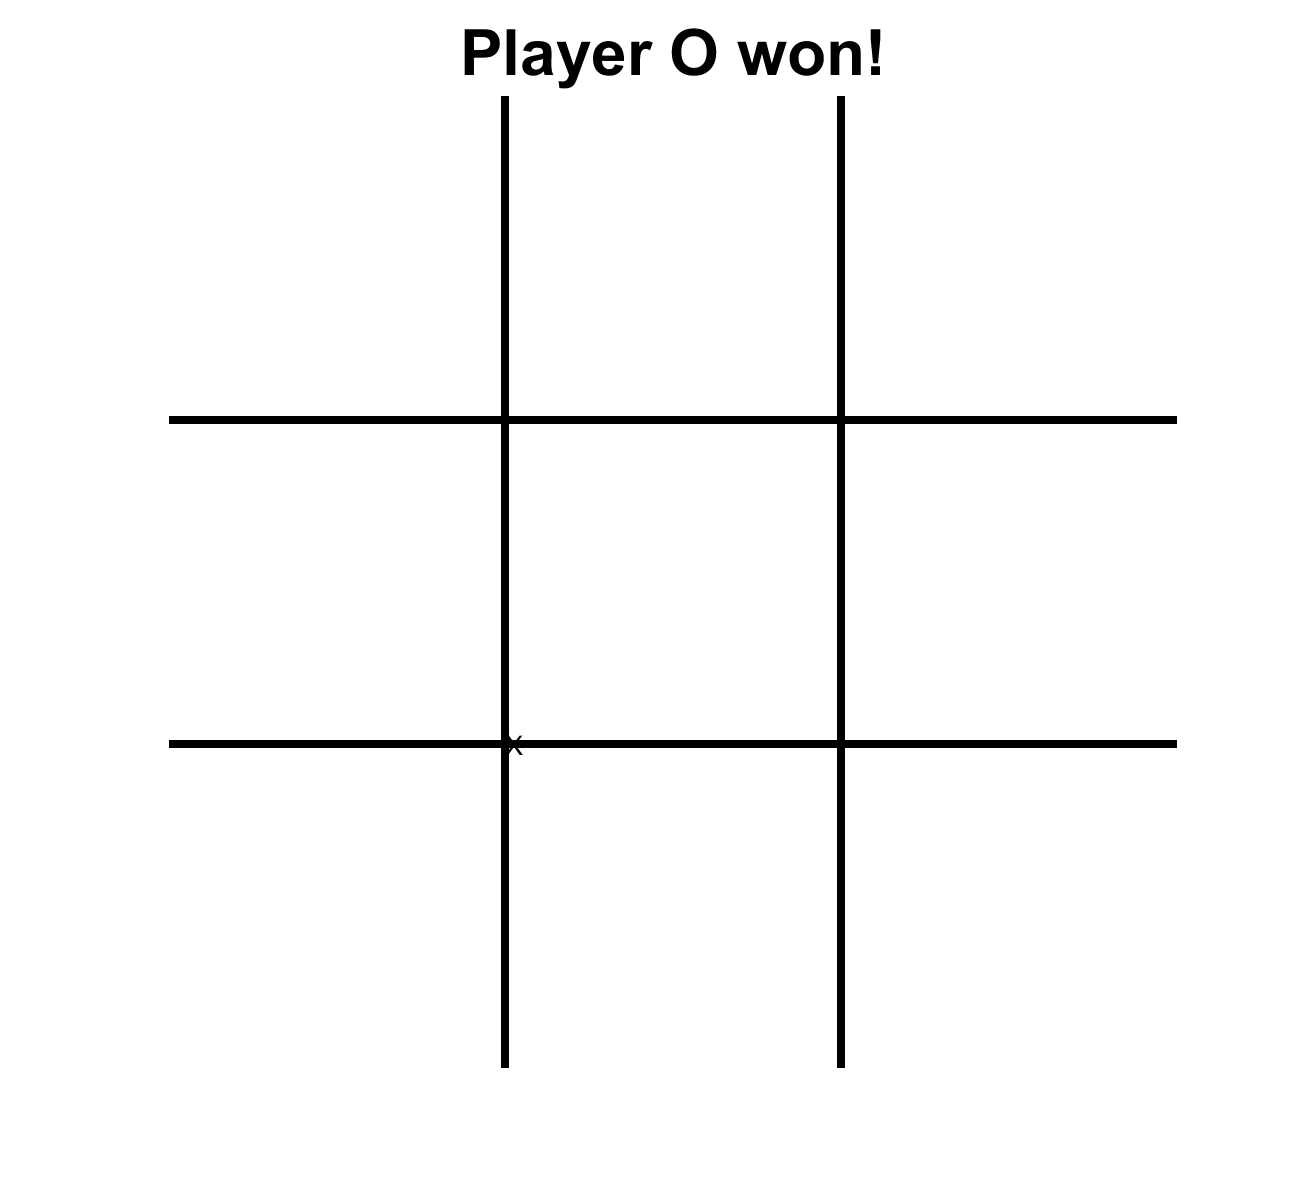

text(2,2,'X')

Clearly, we need to adjust the size and location of the X. Play around with different value to figure out a good offset value.

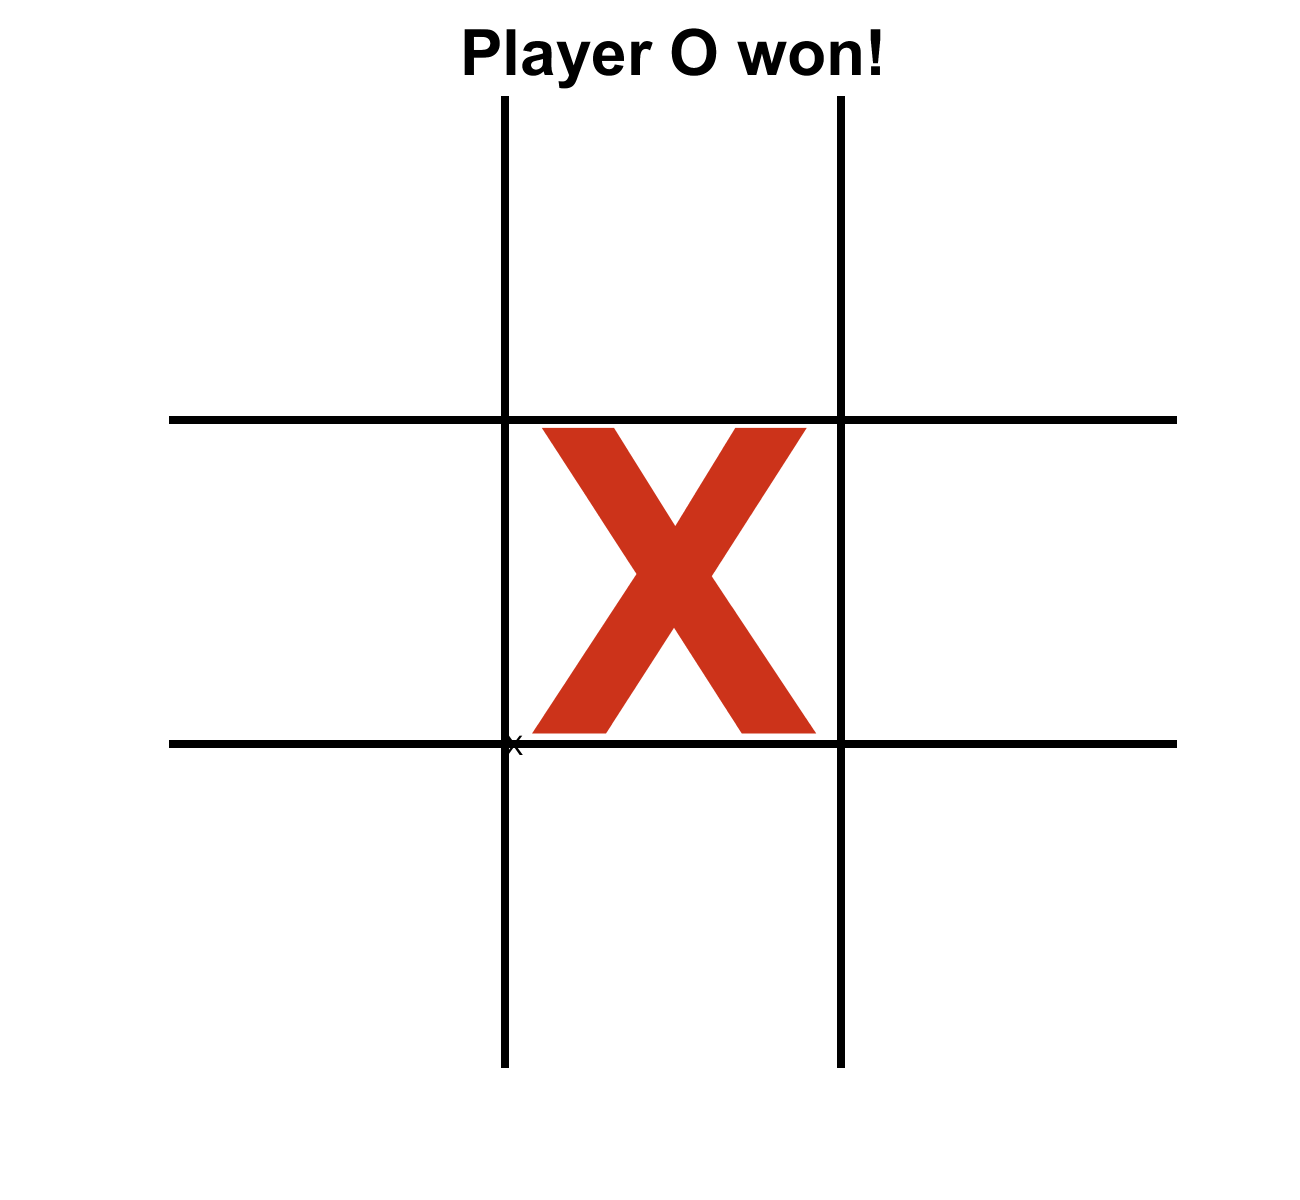

X_x_offset = 0.08;
X_y_offset = 0.55;
text(2 + X_x_offset,2 + X_y_offset,'X','FontSize',160,'FontWeight','bold','Color',[0.8,0.2,0.1])

Example 3:

Now, place an "O" in the left center space.

Note: The bottom left corner of the left center space is located at (2,1), but we now we will have to offset this as well. Let's see if the "X" offset values work for "O".

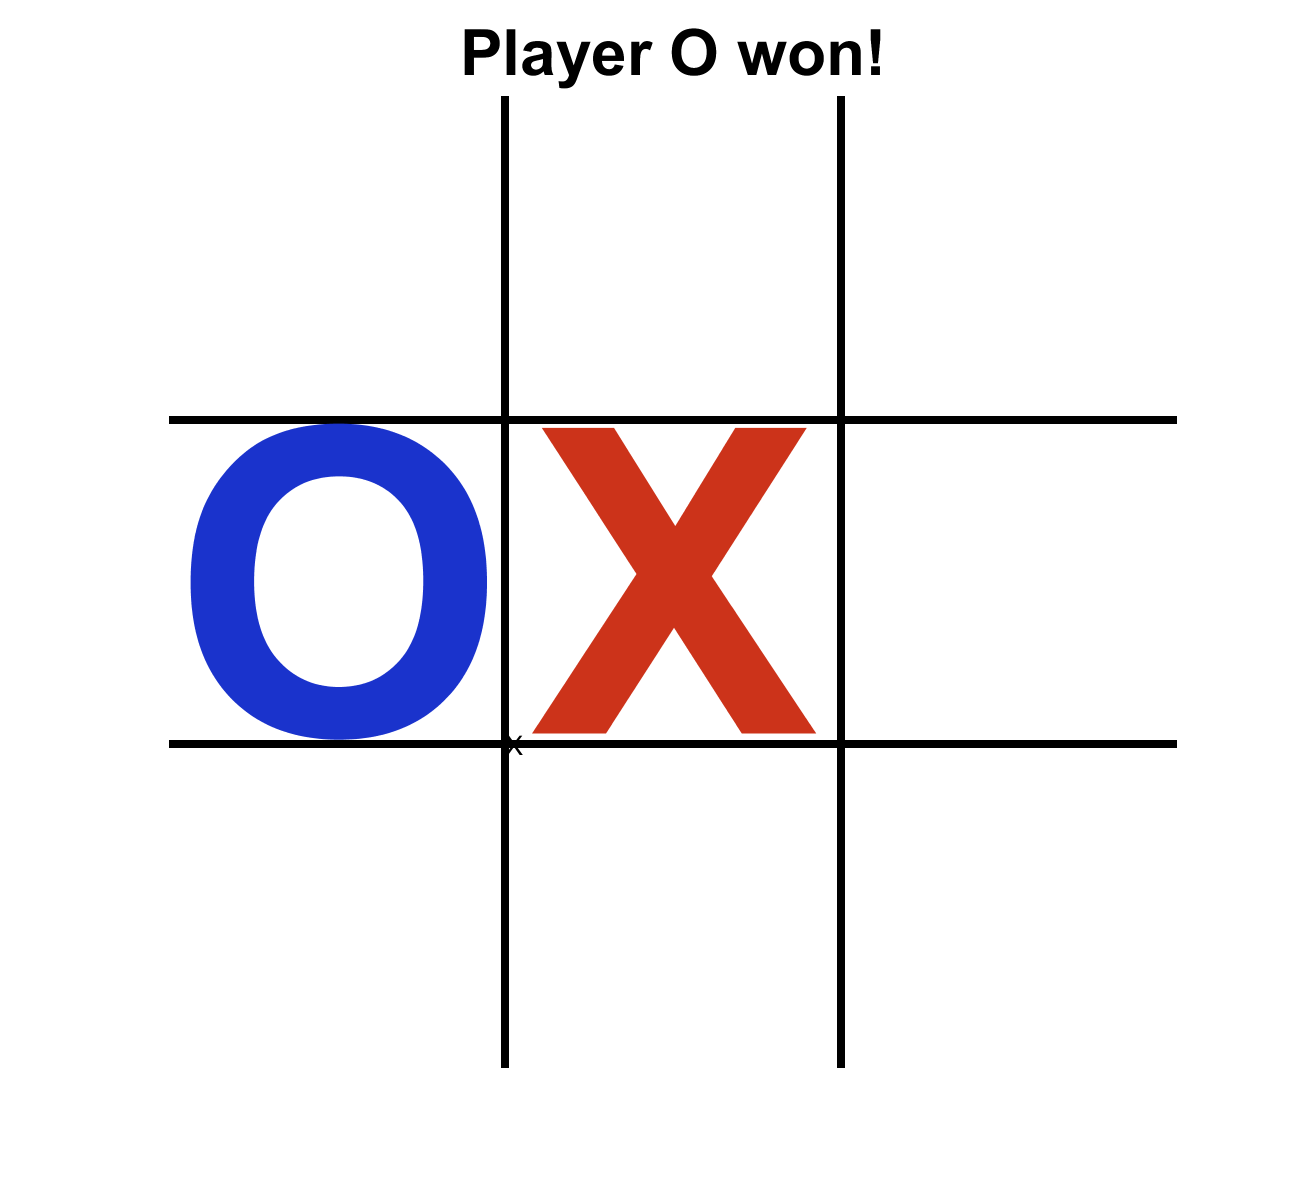

O_x_offset = 0.01;
O_y_offset = 0.545;
text(1 + O_x_offset,2 + O_y_offset,'O','FontSize',160,'FontWeight','bold','Color',[0.1,0.2,0.8])

#### `ginput` command

Finally, the last thing you need to do is be able to mouse-click on the game board to place your moves. This can be done using the `ginput` command.

Example 4:

Click on the game board again and, in the title, display the coordinates that you clicked on.

*Note: When you run this section, the figure will open up outside this script file. Click on this figure, not the figure in the script file.*

coords = ginput(1);
title(['You clicked on point = (',num2str(coords(1)),',',num2str(coords(2)),')'])

Example 5:

Click on the game board again and, in the title, display the coordinates (as rounded down integers) that you clicked on. 

coords = floor(ginput(1));
title(['You clicked on point = (',num2str(coords(1)),',',num2str(coords(2)),')'])

Example 6:

Finally, write a loop that takes 5 clicks on the game board again and, in the title, display the absolute index of the game board space that you clicked on. 

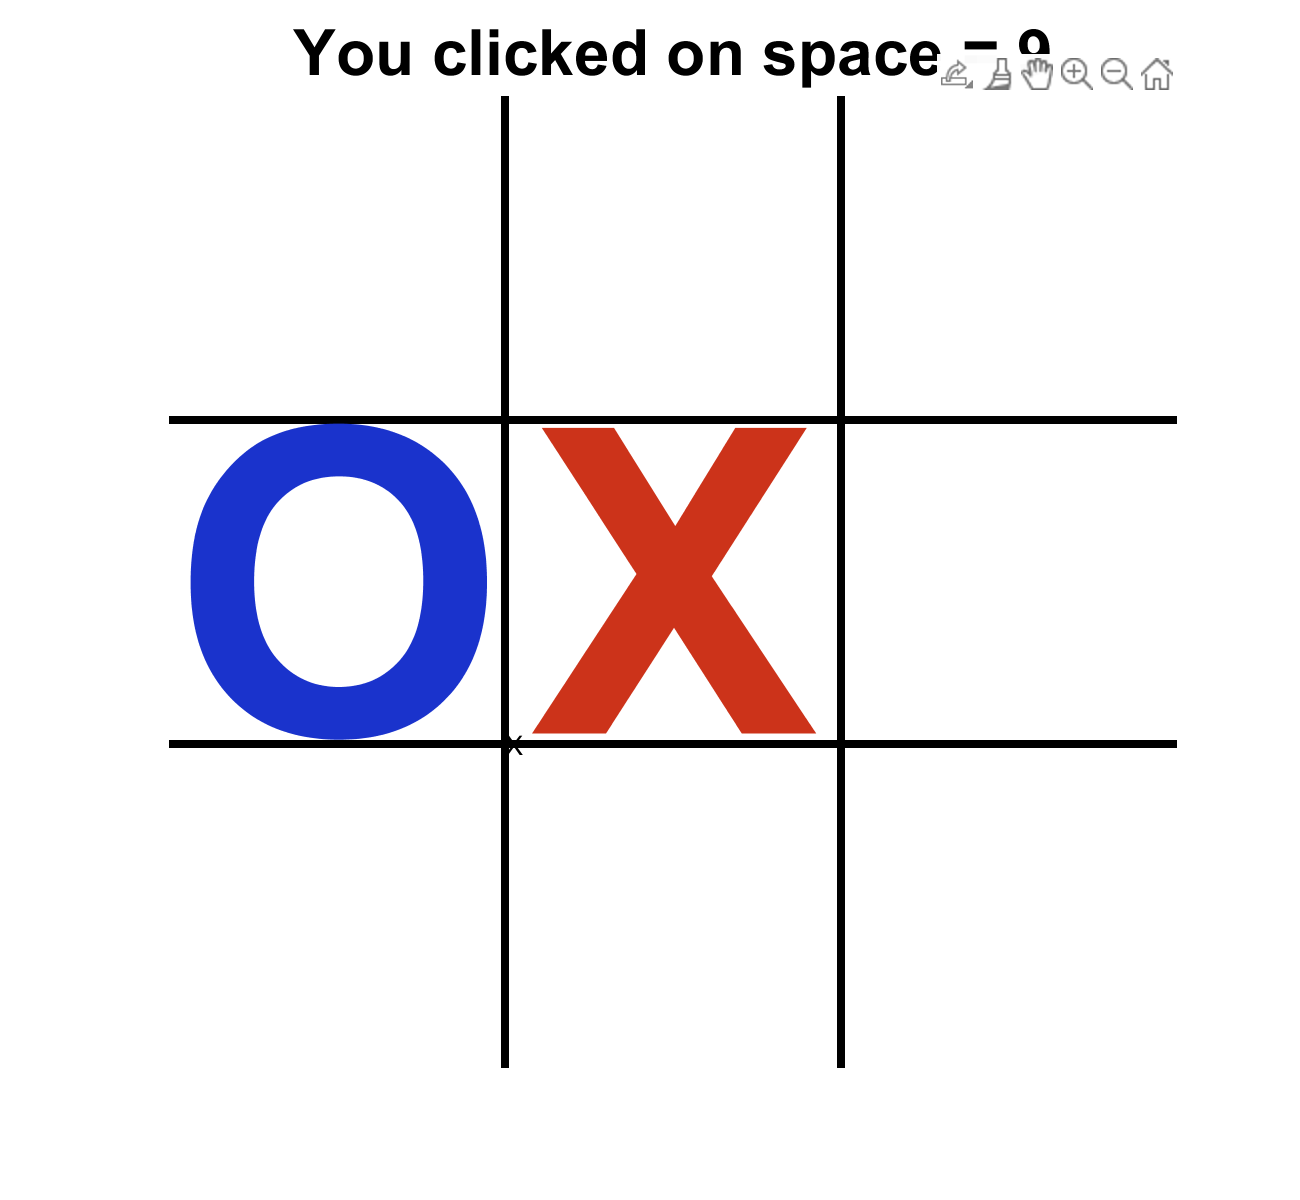

clicks = 0; % number of mouse-clicks
while clicks < 5
    coords = floor(ginput(1));
    clicks = clicks + 1;
    % x,y coordinates to row,column conversion
    row = 4-coords(2);
    col = coords(1);   
    absolute_index = row + 3*(col-1);  % row,column to absolute index formula
    title(['You clicked on space = ',num2str(absolute_index)])  
end

Notice that these values match perfectly with the location on your `game_state` matrix.